# Principles of Supervised Learning

In supervised learning we build a learner (model) that takes input (data) and produces output (data).

It is assumed that training data is available - i.e. (input, output) pairs that give the correct/true output for a specific input.

The input is often a vector, $\mathbf{x} = (x_1,\ldots,x_d)$ with inputs $x_i$ often called features or simply variables.  

The output, $r$ is often a scalar (the extension to vector outputs is often easy), often called the target, predictor or response variable.  A training set with $N$ data points would then be: $\mathcal{X} = \{\mathbf{x}^t,r^t\}^N$

The two main supervised learning problems:

- Classification - e.g. binary or two-class classification, $r \in [0,1]$

- Regression - e.g. univariate regression, $r \in I\!\!R^1$

load fisheriris
size(meas)

ans =    150     4


meas(1:5,:)

ans =     5.1000    3.5000    1.4000    0.2000
    4.9000    3.0000    1.4000    0.2000
    4.7000    3.2000    1.3000    0.2000
    4.6000    3.1000    1.5000    0.2000
    5.0000    3.6000    1.4000    0.2000


size(species)

ans =    150     1


species(1:5)

ans = 5×1 cell array
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}


A supervised learner is often trained by defining an **error or loss function** over the training set and then minimizing this error function.  However the true goal is to produce a model capable of **generalisation**: the error function on unseen data (or, the expected value over all unseen data).

The simplest way to get an indication of the generalisation error is to evaluate the model on a test set of data.

## Linear Regression

We won't worry too much about the **training** of this model right now - see next week.

openExample('matlab/LinearRegressionShortExample')


## Linear Discriminant Analysis

Essentially we can make a classifier from a linear regression model by "squashing" the output through a step (or sigmoidal shaped) function.  A sigmoid leads us to two very well known methods: **linear discriminant analysis** and **logistic regression**.  We will look at the details and differences later.

open('c:\MarcusG\Teaching\comp4702\2018\Lectures\hackedCreateAndVisualizeDiscriminantAnalysisClassifierExample.mlx')

## **Nearest Neighbour Classification**

One of the simplest methods of all!  To train, simply store the training set.  To predict (for a given test point), find the nearest point in the training set.  Predict whatever class label that training point has.  Note:

- Choice of distance metric is a key descision and there are many possibilities

- Rather than using the nearest neighbour, we can generalise to $k$-nearest neighbours (kNN).

From [HTF]:

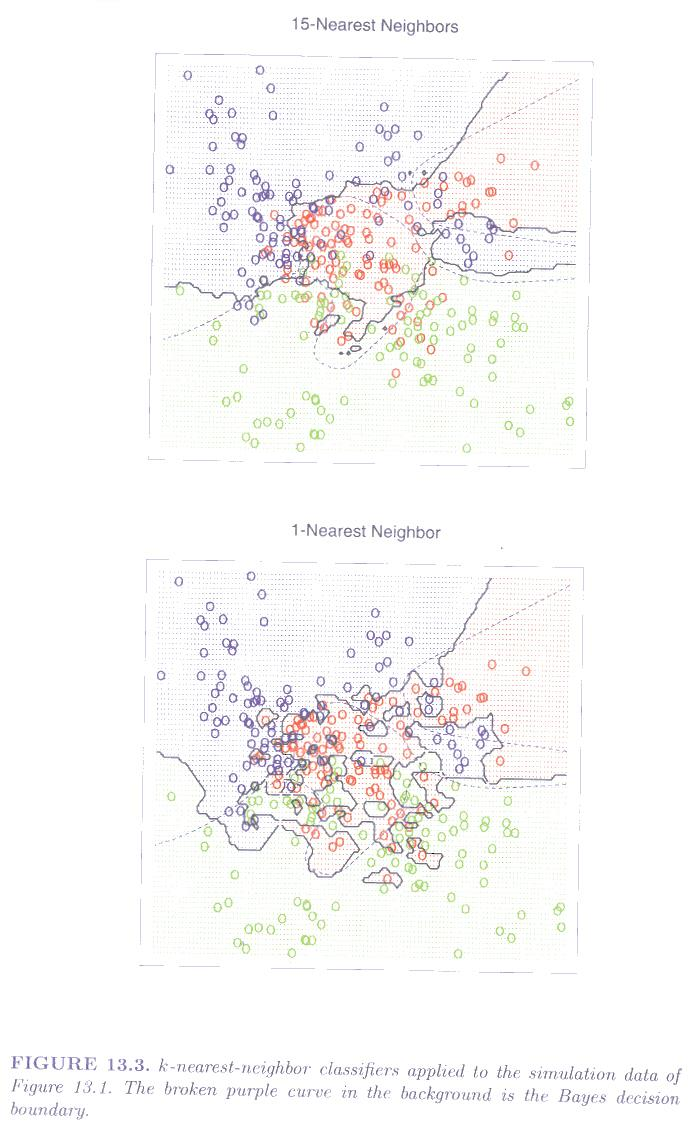

The curve(s) that separate the classes in the feature space are called the **decision boundary** or the **discriminant**.

Matlab has kNN classification functions but they have many other options, tricks and features added (some by default).  We need to be careful when using ML software libraries to understand the assumptions and effects of these options, tricks and features.

## Model Selection Problem

Learning is an ill-posed problem.  It isn't about finding a unique, "best" model.

Inductive bias: every technique comes with it's own "biases" that will effect performance on a given problem.

There is a fundamental tradeoff between:

- Model complexity (but how to measure "complexity"?!). If the model is too simple, it might **underfit** the training data, leading to poor prediction on test data.  If the model is too complex, it might **overfit** the training data, leading to poor prediction on test data.

- Training set size

- Generalisation error

## A Summary of Supervised Learning

- Model (with parameters, $\theta$): $g(\mathbf{x}|\theta)$

- Loss function: $E(\theta|\mathbf{x})$

- Optimisation: $\theta^* = \arg \min_{\theta} E(\theta|\mathbf{x})$